# Shaw-Pierre example

We consider the two-degree-of-freedom mechanical system studied by Shaw and Pierre [1], with an additional damper connecting the left mass to the wall. The system was originally studied in the $\left(q_1, q_2 \right)$ coordinates, whereas here we use the coordinates $y_1 = q_1$ and $y_2 = q_2 - q_1$. This introduces non-normality between slow and fast linear subsapces in the phase space.

[1]  S. Shaw and C. Pierre. Normal modes for non-linear vibratory systems. J. Sound Vib., 164(1): 85–124, 1993. 

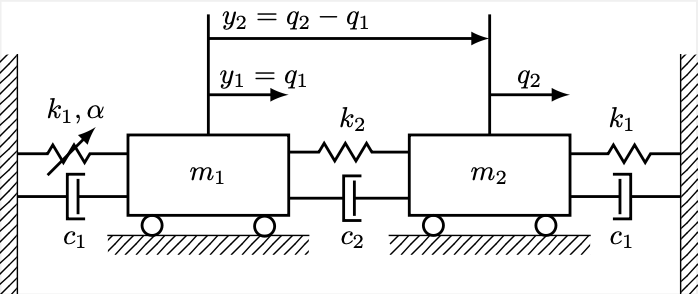

clearvars
close all

## Example setup

The governing equations are


$$\mathbf{M}\mathbf{\ddot{y}} + \mathbf{C}\mathbf{\dot{y}} + \mathbf{K}\mathbf{y} + \mathbf{f}_\mathrm{nl} = \mathbf{0},$$


with $ \mathbf{y} = \left(y_1,\, y_2 \right)^\mathrm{T}$ and 


$$\mathbf{M} = \left[ \begin{array}{cc}
    m_1 & 0\\
    m_2 & m_2
\end{array} \right],\quad
 \mathbf{C} = \left[ \begin{array}{cc}
    c_1 & -c_2\\
    c_1 & c_1 + c_2
   \end{array} \right],\quad
\mathbf{K} = \left[ \begin{array}{cc}
    k_1 & -k_2\\
    k _1& k_1 + k_2
 \end{array} \right],\quad
\mathbf{f}_\mathrm{nl} = \left[ \begin{array}{cc}
    -\alpha y_1^3 \\
    0
     \end{array} \right].$$


n = 2;
k1 = 1;
k2 = 3 + 0.325;
c1 = 0.05;
alpha = 0.5;
factor = @(beta_alpha) 1/2 * beta_alpha;
c2_fun = @(beta_alpha) c1 * factor(beta_alpha);
beta_alpha_red = 0.4;
c2 = c2_fun(beta_alpha_red);
[F,A,M,C,K,F_nl] = SP(k1,k2,c1,c2,alpha,0,0);

T_tilde = [1 0; -1 1];
M_t = M/T_tilde;
C_t = C/T_tilde;
K_t = K/T_tilde;

T = [1 0 0 0; -1 1 0 0; 0 0 1 0; 0 0 -1 1];
A_t = T*A/T;

F_t = @(t,eta) A_t * eta + T*F_nl(t,T\eta);
[V_t,D_t,lambda_t] = eigSorted(A_t);

**Preliminary analysis**

We approximate the primary SSM from SSMTool and compare trajectories lying on the primary and fractional SSMs. Compute the backbone curves. If the initial condition lies outside the primary SSM (on a fractional SSM), then its evolution in time develops oscillations in the backbone curve.

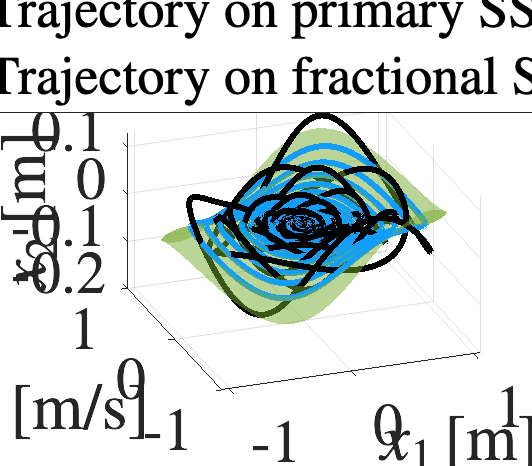

tSpan_decay = linspace(0,400,1e4);
[t_t, x_t, t_t_off, x_t_off, x0_ssm_t] = plot_SSMTool(F_t,tSpan_decay,V_t);

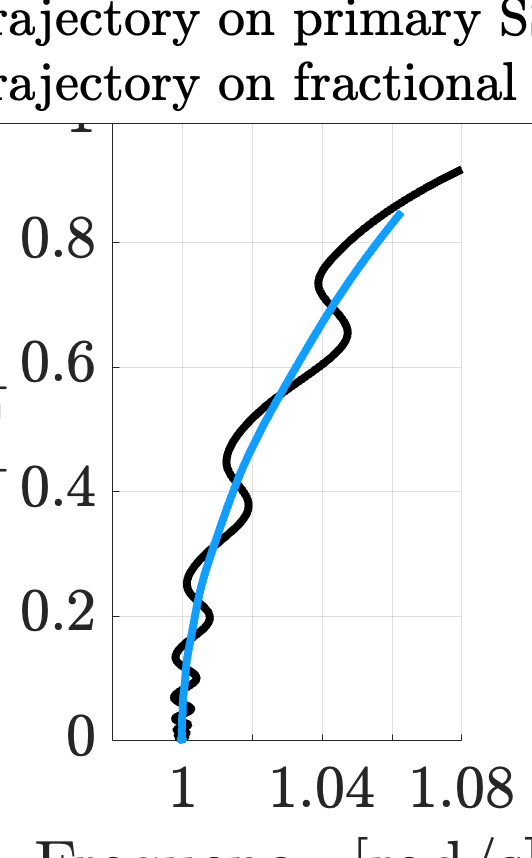


kmean = 1;       
[amp_ssm,freq_ssm,damp_ssm,time_ssm] = PFFk(t_t,x_t(1,:),kmean);
[amp_off,freq_off,damp_off,time_off] = PFFk(t_t_off,x_t_off(1,:),kmean);

lim = 1e-3;
[freq_spline_ssm, amp_spline_ssm] = bc_spline(freq_ssm, amp_ssm, lim);
[freq_spline_off, amp_spline_off] = bc_spline(freq_off, amp_off, lim);

f = figure;
f.Position = [1028,132,455,734];
hold on 
grid on 
plot(freq_spline_ssm, amp_spline_ssm,'color',[0.07,0.62,1.00],'LineWidth',4,'DisplayName','Trajectory on primary SSM')
plot(freq_spline_off, amp_spline_off,'-k','LineWidth',4,'DisplayName','Trajectory on fractional SSM')

xlim([0.98 1.08])
xlabel('Frequency [rad/s]','Interpreter','Latex')
ylabel('$|x_1|$','Interpreter','Latex')
set(gca,'FontSize',30,'TickLabelinterpreter','latex')
h = get(gca,'Children');
set(gca,'Children',[h(2) h(1)], ...
    'OuterPosition',[0.017728808895572,0.021298756734844,0.930686646616658,0.907894174771129], ...
    'InnerPosition',[0.213186813186813,0.136557610241821,0.654945054945055,0.725840209921667], ...
    'Position',[0.213186813186813,0.136557610241821,0.654945054945055,0.725840209921667]);
legend([h(2) h(1)],'Location','NW','Interpreter','latex','Position',[0.075229572070824,0.889168935736186,0.850496061555631,0.09441417049647])


xData = cell(1,2);
xData{1,1} = t_t_off;
xData{1,2} = x_t_off;

xOutput = @(x) x(1,:);
endTime = xData{1,1}(end);

## SSM dimension and truncation of data

The dimension of the SSM ($\texttt{SSMDim}$) and the initial truncation time ($\texttt{startTime}$) are automatically computed based on the modal content detected by spectrogram analysis. This procedure is strictly valid for oscillatory systems, which are the most commonly found in engineering applications. 

Set $\texttt{automatic = false}
$ if you want to enforce a specific dimension of the SSM and truncation time.

automatic = false;
if automatic
    indplot = 1;
    [startTime, indStartTime, SSMDim] = SSM_startTime(xData(1,:),indplot);
    sliceInt = [startTime, endTime];
else
    SSMDim = 2;
    sliceInt = [10, endTime];
end

## Oblique projection and delay embedding 

We compute the linear oblique projection that best approximates the direction of the fast subspace from data. Obliquely projected coordinates serve as the reduced coordinates for the SSM parametrization, when the linear part of the dynamical system is non-normal. This procedure is strictly valid for oscillatory systems. The linear approximation of the projection is most accurate when computed from the linear regime of the data. In the suboptimal case when the linear regime of the data is unknown, the oblique projection is automatically computed across the entire data range.

Set $\texttt{automatic = false }$ in order to enforce the computation of the oblique projection in the linear regime, defined by the parameter $\texttt{lim}$, for increased accuracy.

Set $\texttt{oblique\_projection = false}$ in order to apply the standard normal projection. 

overEmbed = 0;
ShiftStep = 1;
oblique_projection = true;

if ~automatic 
    lim = 2e-7; 
    indStartTime = regimeLinear(xData,lim);
end

[yData, P, V_trunc_slow,data_non_projected,data_non_projected_trunc] = obliqueProjection(xData,indStartTime,SSMDim, overEmbed, ShiftStep, 'flag_end',0,'oblique_projection',oblique_projection);

The 8 embedding coordinates consist of the 4 measured states and their 1 time-delayed measurements.
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          17          2.23489                          8.24
     1          51         0.961639      0.0471067            5.2  
     2          68          0.15284              1          0.711  
     3          85         0.119514              1           0.64  
     4         102        0.0121347              1          0.462  
     5         119       0.00358702              1          0.266  
     6         136      5.98971e-05              1         0.0092  
     7         153      3.70043e-05              1        0.00425  
     8         170      3.61718e-05              1       0.000191  
     9         187      3.61704e-05              1        6.4e-05  
    10         204        3.617e-05              1       5.38e-05  
    11         22

The function $\texttt{obliqueProjection}$ also arranges the scalar measurements in an observable space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space. The dimensionality of the observable space can be further expanded with the parameter `overEmbed` to facilitate recognition of the manifold from data.

We form a multi-dimensional observable by stacking $d$ subsequent scalar measurements $x$ in a vector $y$, and we will later use the trajectories in this augmented space for the manifold fitting.


$$\left[\begin{array}{c}y_{1} \\ \vdots \\ y_{i+1} \\ \vdots \\ y_{d+1}\end{array} 
\right] = \left[\begin{array}{c}x(t^k) \\ \vdots \\ x(t^k+i\Delta t) \\ \vdots 
\\ x(t^k+d\Delta t)\end{array} \right]$$


The total number of embedded coordinates is $2m+1 + \texttt{overEmbed}$.

## SSM model reduction

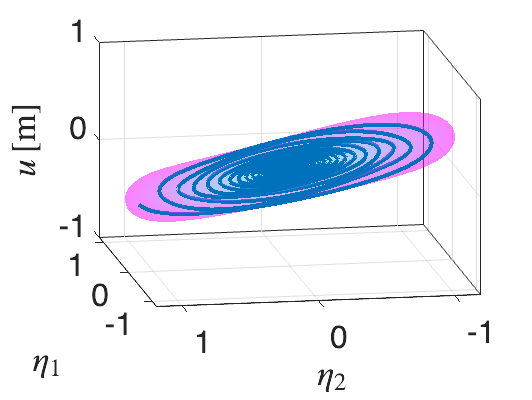

yDataTrunc = sliceTrajectories(yData, sliceInt);

indTrain = 1;
indTest = 1;

% manifold parametrization
SSMOrder = 5;

% compute the reduced coordinates as the oblique projection of the
% coordinates in the full observable space onto the slow subspace 

[IMInfo, ~, ~] = IMGeometry(yDataTrunc(indTrain,:), SSMDim, 1,'V_e',V_trunc_slow);
SSMChart_P = @(x) IMInfo.parametrization.tangentSpaceAtOrigin'*P*x;
etaData = projectTrajectories(IMInfo, yData);
etaDataTrunc = projectTrajectories(IMInfo, yDataTrunc);

yData_original = data_non_projected;
yData_original_Trunc = sliceTrajectories(yData_original, sliceInt);
[IMInfo, SSMChart, SSMFunction] = IMGeometry(yData_original_Trunc(indTrain,:), SSMDim, SSMOrder, 'reducedCoordinates', etaDataTrunc(indTrain,:));
IMInfo.chart.map = SSMChart_P;

plotSSMWithTrajectories(IMInfo, 1, yData_original_Trunc(indTrain,:))
view(-100,20); zlabel('$u \, [$m$]$','Interpreter','latex')

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1      6.83937e-05                      0.000435
     1           4      4.11047e-05             91       0.000417  
     2           5      1.77037e-05              1       0.000236  
     3           6       8.8784e-06              1       0.000236  
     4           7      2.04931e-06              1       9.91e-05  
     5           8      9.54006e-07              1       4.39e-05  
     6           9      6.61909e-07              1       3.15e-05  
     7          10      4.67667e-07              1        2.6e-05  
     8          11      3.52893e-07              1       1.47e-05  
     9          12      3.25793e-07              1       4.66e-06  
    10          13      3.17519e-07              1       4.04e-06  
    11          14


% manifold reduced dynamics 
ROMOrder = 5;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), ...
    'R_PolyOrd', ROMOrder, 'style', 'normalform');

## Backbone curves

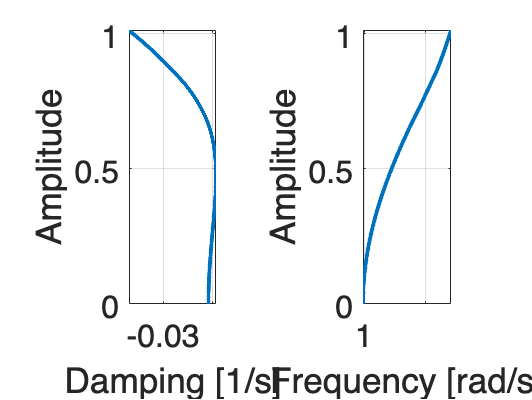

omega_0 = imag(lambda_t(1));
zData = transformTrajectories(RDInfo.inverseTransformation.map, etaData);
rhoCal = abs(zData{indTest(1),2}(1,1));
amplitudeFunction = @(x) x(1,:);
BBCInfo = backboneCurves(IMInfo, RDInfo, amplitudeFunction, rhoCal);

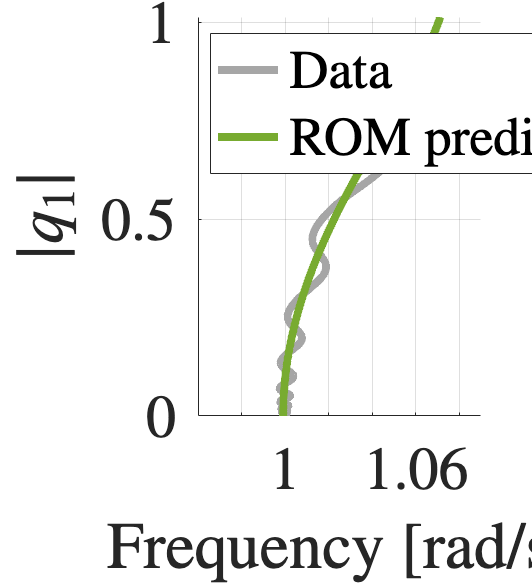



kmean = 1;       
[amp_sol,freq_sol,damp_sol,time_sol] = PFFk(t_t_off, xOutput(x_t_off),kmean);
[amp_z,freq_z,damp_z,time_z] = PFFk(t_t_off,xOutput(yData{1,2}),kmean);

lim = 1e-3;
[freq_spline_sol, amp_spline_sol] = bc_spline(freq_sol, amp_sol, lim);
[freq_spline_z, amp_spline_z] = bc_spline(freq_z, amp_z, lim);
fig = figure;
fig.Position = [476,255,560,617];
hold on 
grid on 
plot(freq_spline_sol, amp_spline_sol,'Color',[0.65,0.65,0.65],'LineWidth',4,'DisplayName','Data')
% plot(freq_spline_z, amp_spline_z,'k-','LineWidth',4,'DisplayName','Projected data')
plot(BBCInfo.frequency, BBCInfo.amplitude,'color',[0.47,0.67,0.19],'LineWidth',4,'Displayname','ROM prediction')
xlabel('Frequency [rad/s]','Interpreter','Latex')
ylabel('$|q_1|$','Interpreter','Latex')
set(gca,'FontSize',30,'TickLabelInterpreter','Latex', ...
    'OuterPosition',[0,0,1,1.05]);
xlim([0.96 1.09])
legend('location','NW','Interpreter','latex')

## Forced response curves

fig = figure;
fig.Position = [476,255,560,617];
hold on 
grid on 
plot(freq_spline_sol, amp_spline_sol,'Color',[0.65,0.65,0.65],'LineWidth',4,'DisplayName','Backbone from data')

xlabel('Frequency [rad/s]','Interpreter','Latex')
ylabel('$|q_1|$','Interpreter','Latex')
set(gca,'FontSize',30,'TickLabelInterpreter','Latex', ...
    'OuterPosition',[0,0,1,1.05]);
xlim([omega_0-0.5 omega_0+0.5])
xlim([0.96 1.09])
legend('location','NW','Interpreter','latex')

omegaSpan_bottom = 0.98;
omegaSpan_top = 1.08;

% FRC from the reduced order model 
amp_lim = 1;
amplitudeCal = [0.0435 0.108709 0.2165 0.322 0.43 0.533 0.635];
forcingSpan = zeros(1,length(amplitudeCal));
for iCal = 1:length(amplitudeCal)
   [~,pos] = min(abs(BBCInfo.amplitude-amplitudeCal(iCal)));
   forcingSpan(iCal) = -BBCInfo.amplitudeNormalForm(pos)*BBCInfo.damping(pos);
end
[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1);

Forced SSM reduced-order model assumes external forcing only along the tangent (modal) subspace at the origin. 


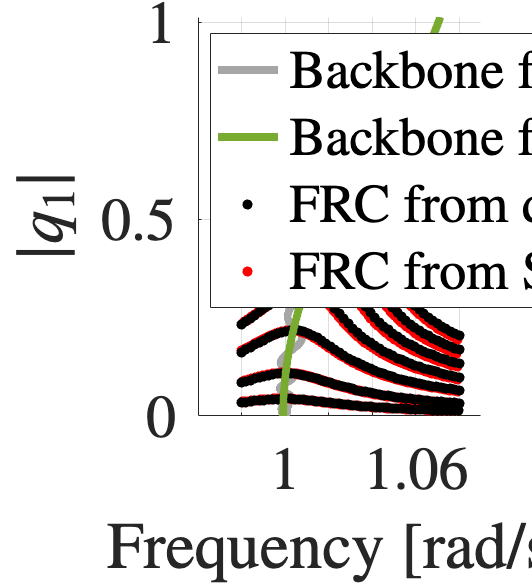

FRCData = analyticalFRC(IMInfoF,RDInfoF,forcingSpan,amplitudeFunction);

for ii = 1:length(amplitudeCal)
    
    forced_freq = FRCData.(['F' num2str(ii)]).Freq(:);
    forced_amp = FRCData.(['F' num2str(ii)]).Amp(:);
    
    index_plot = find(forced_freq>=omegaSpan_bottom & forced_freq<=omegaSpan_top & forced_amp<amp_lim);
    forced_freq_plot = forced_freq(index_plot);
    forced_amp_plot = forced_amp(index_plot);
    
    if ii == 1
        plot(forced_freq_plot, forced_amp_plot,'.r','LineWidth',1,'MarkerSize',15,'DisplayName','FRC from SSM model')
    else
        plot(forced_freq_plot, forced_amp_plot,'.r','LineWidth',1,'MarkerSize',15,'HandleVisibility','off')
    end

end


% generate forced response curves from the original system 
freq_vect = linspace(omegaSpan_bottom,omegaSpan_top,50);
amp_vect = [0.001 0.0025 0.005 0.0075 0.01 0.0125 0.015];

for jj = 1:length(amp_vect)
    ampl_FRC = zeros(size(freq_vect));
    freq_FRC = zeros(size(freq_vect));
    amp_curr = amp_vect(jj);
    for ii = 1:length(freq_vect)
        Omega = freq_vect(ii);
        F_forced = @(t,x) F_t(t,x) + amp_curr * cos(Omega*t);
        [t_forced, x_forced] = ode45(F_forced, tSpan_decay, x0_ssm_t);
        t_forced = transpose(t_forced);
        x_forced = transpose(x_forced);
 
        signal = x_forced;
        data = cell(1,2);
        data{1,1} = t_forced;
        data{1,2} = signal;

        kmean = 1;
        [amp_frc,freq_frc,~,~] = PFFk(data{1,1},data{1,2}(1,:),kmean);
        amp_frc = amp_frc(~isnan(freq_frc));
        freq_frc = freq_frc(~isnan(freq_frc));
        ampl_FRC(ii) = amp_frc(end);
        freq_FRC(ii) = 2*pi*freq_frc(end);
    
    end
    
    if jj == 1
        plot(freq_FRC, ampl_FRC,'k.','LineWidth',1,'MarkerSize',15,'DisplayName','FRC from data')
    else
        plot(freq_FRC, ampl_FRC,'k.','LineWidth',1,'MarkerSize',15,'HandleVisibility','off')
    end

end

plot(BBCInfo.frequency, BBCInfo.amplitude,'color',[0.47,0.67,0.19],'LineWidth',4,'Displayname','Backbone from SSM model')

h = get(gca,'Children');
legend([h(4) h(1) h(2) h(3)]);

## Additional functions

function [F,A,M,C,K,F_nl] = SP(k1,k2,c1,c2,alpha,epsilon,Omega)

M = eye(2);
C = [c1 + c2, -c2;
    -c2, c1+c2];
K = [k1 + k2, -k2;
    -k2, k1+k2];

f_nl = @(t,x) [alpha * x(1).^3; 0];
f_ext = @(t,x) [epsilon * cos(Omega * t); 0];

A = [zeros(2) eye(2);
    -M\K -M\C];

F_nl = @(t,x) [zeros(2,1); -M\f_nl(t,x)] + [zeros(2,1); M\f_ext(t,x)];

F = @(t,x) A * x + [zeros(2,1); -M\f_nl(t,x)] + [zeros(2,1); M\f_ext(t,x)];

end

function plotSSM_ssmtool()

    load('XX.mat','XX');
    load('YY.mat','YY');
    load('ZZ.mat','ZZ');
    
    % customFigure; 
    classicColors = colororder;
    fig = figure;
    hold on 
    grid on 
    fig.Position = [696,337,560,491];
    h = surf(XX,YY,ZZ,'HandleVisibility','off');
    h.FaceColor = classicColors(1,:);
    h.FaceColor = [0.47,0.67,0.19];
    h.EdgeColor = 'none';
    h.FaceAlpha = .5;
    xlabel('$x_1 \, [$m$]$','Interpreter','latex','FontSize',30,'Position',[0.104356912417099,-1.207746549280131,-0.237632362684135]); 
    zlabel('$x_2 \, [$m$]$','Interpreter','latex','FontSize',30,'Position',[-1.467103409674007,1.14325138688222,-0.034514954675319]); 
    ylabel('$x_3\, [$m/s$]$','Interpreter','latex','FontSize',30,'Position',[-1.259382664235982,-0.112477314059568,-0.240349125976296]); 
    view(-20.122788542926202,34.822508198240442)
    set(gca,'FontSize',30,'TickLabelInterpreter','latex', ...
        'OuterPosition',[0.050396865838005,0.068582337162595,0.936174462145399,0.786624455018657], ...
        'InnerPosition',[0.23954969276697,0.162583751291155,0.66545030723303,0.634255930702729], ...
        'Position',[0.23954969276697,0.162583751291155,0.66545030723303,0.634255930702729]);
     
end


function [freq_fit_spline, amp_fit_spline] = bc_spline(freq, amp, lim)
    freq_spline = flip(2*pi*freq(amp>lim));
    amp_spline = flip(amp(amp>lim));
    amp_spline = amp_spline(~isnan(freq_spline));
    freq_spline = freq_spline(~isnan(freq_spline));
    amp_fit_spline = linspace(amp_spline(1),amp_spline(end),1000);
    freq_fit_spline = spline(amp_spline,freq_spline,amp_fit_spline);
end

function [t_t, x_t, t_t_off, x_t_off, x0_ssm_t] = plot_SSMTool(F_t,tSpan_decay,V_t)

rho_train_t = 0.7;
theta_train_t = 0;
ztrain_t = rho_train_t * exp(1i * theta_train_t);
ztrain_t = [ztrain_t; conj(ztrain_t)];
plotSSM_ssmtool
load('x0_ssm_t.mat','x0_ssm_t');
[t_t, x_t] = ode45(F_t, tSpan_decay, x0_ssm_t);
t_t = transpose(t_t);
x_t = transpose(x_t);
ratio_first = 1;
ratio_second = 2;
x_ssm_t_complex = V_t\x0_ssm_t;
x_ssm_t_complex_mag = abs(x_ssm_t_complex);
x_ssm_t_complex_phase = angle(x_ssm_t_complex);
new_rho = [x_ssm_t_complex_mag(1) * ratio_first; x_ssm_t_complex_mag(2) * ratio_second; x_ssm_t_complex_mag(3) * ratio_first; x_ssm_t_complex_mag(4) * ratio_second];
new_x_ssm_t_complex = new_rho .* cos(x_ssm_t_complex_phase) + 1i * new_rho .* sin(x_ssm_t_complex_phase);
new_x_ssm_t = V_t * new_x_ssm_t_complex;
x0_t_off = real(new_x_ssm_t);
[t_t_off, x_t_off] = ode45(F_t, tSpan_decay, x0_t_off);
t_t_off = transpose(t_t_off);
x_t_off = transpose(x_t_off);

plot3(x_t(1,:),x_t(3,:),x_t(2,:),'color',[0.07,0.62,1.00],'LineWidth',3,'DisplayName','Trajectory on primary SSM')
plot3(x_t_off(1,:),x_t_off(3,:),x_t_off(2,:),'k','LineWidth',3,'DisplayName','Trajectory on fractional SSM')

legend('location','NE','Interpreter','latex','Position',[0.163971949986049,0.838998539133578,0.691028050013951,0.14114053186234])

end

